# This program creates synthetic EIS data using a circuit model 

The toy model consists of a pure resistor R0 in series with four pairs (Resistor, Constant Phase Element), where the Resistor and Constant Phase Element are connected in parallel.

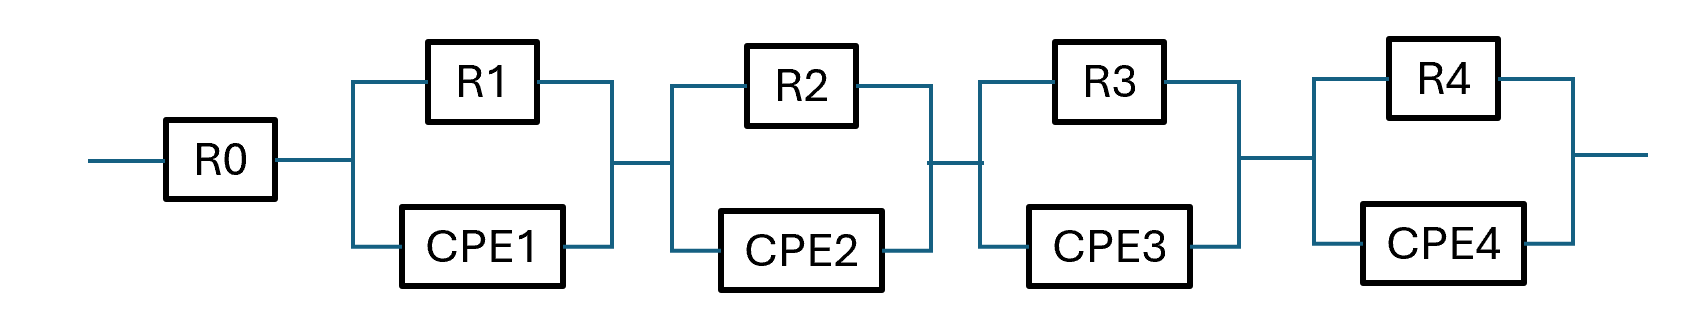

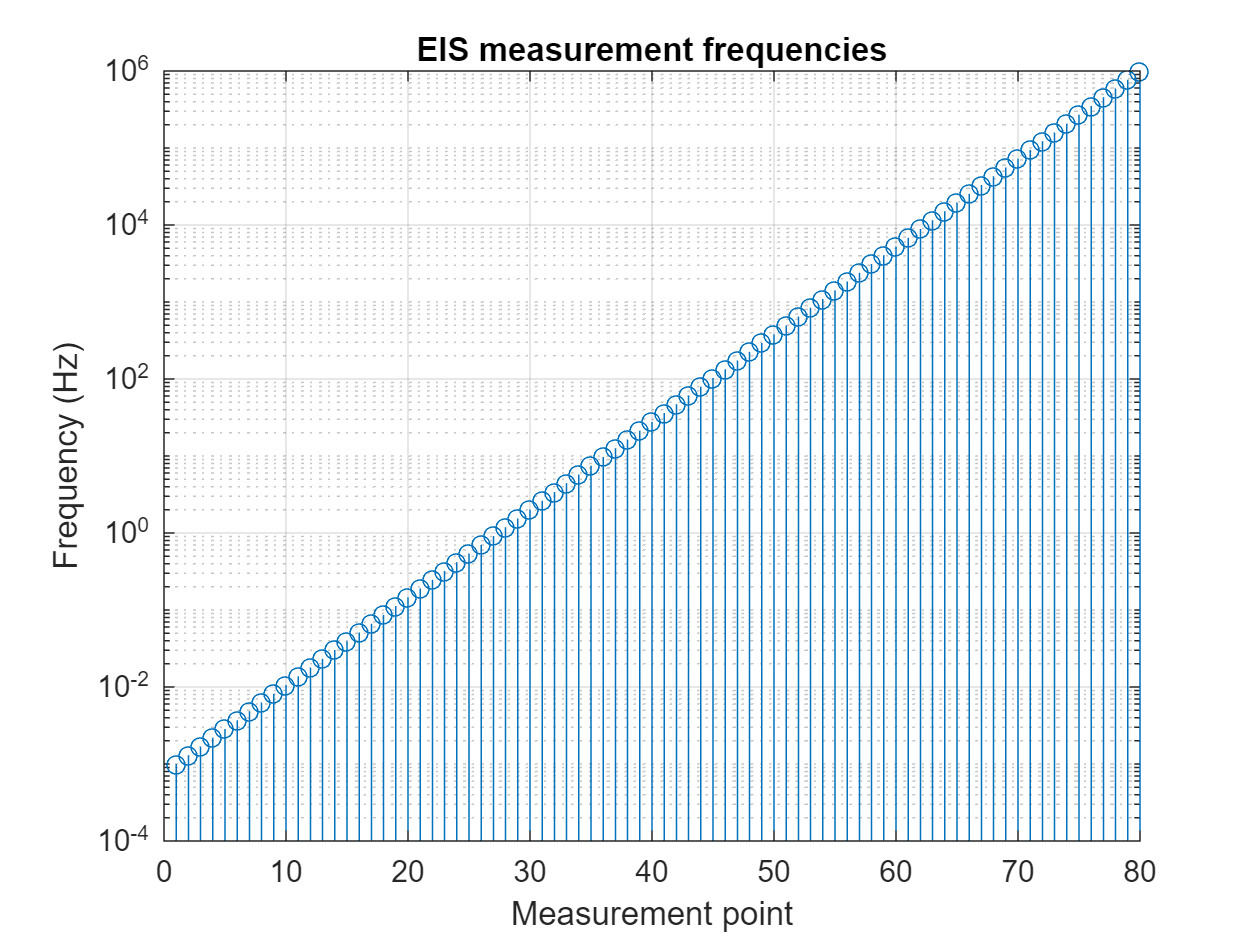

% Circuit parameters. The values are representative for a Li-Ion battery
% cell.

R0 = 0.015; % Ohm
R1 = 0.002;
Tau1 = 0.002; % s
CPE1factor = 0.8;
R2 = 0.02;
Tau2 = 15;
CPE2factor = 0.6;
R3 = 0.1;
Tau3 = 5000;
CPE3factor = 0.9;
R4 = 0.2;
Tau4 = 10000;
CPE4factor = 0.9;

% Frequency vector, representing a hypothetical EIS measurement

% Generally, the frequency range for impedance spectroscopy on Li-ion
% batteries spans from millihertz (mHz) to megahertz (MHz)  
freq_Hz = logspace(-3,6,80)'; % from 0.001 Hz to 1e6 Hz

% Frequency vector in rad/s
freq = 2*pi*freq_Hz; % rad/s

% Display EIS measurement frequencies
figure 
stem(freq_Hz)
set(gca, 'YScale', 'log')
grid on
xlabel("Measurement point")
ylabel ("Frequency (Hz)")
title("EIS measurement frequencies")

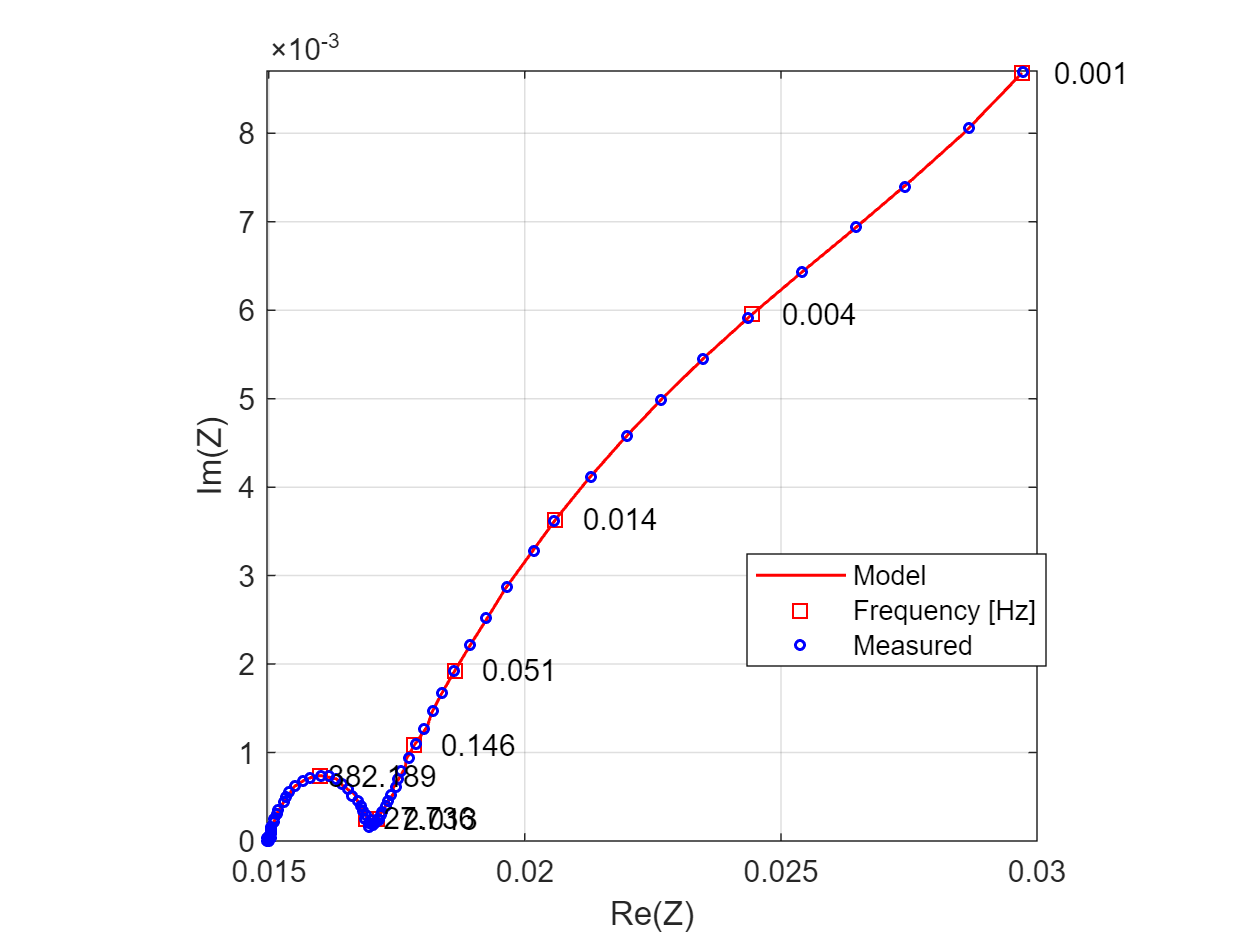


% The impedance for the R0 + parallel(R_n,CPE_n) , with n = 1..4, circuit
Z = R0 + ...
    R1./(1 + Tau1*(freq*1i).^CPE1factor) + ...
    R2./(1 + Tau2*(freq*1i).^CPE2factor) + ...
    R3./(1 + Tau3*(freq*1i).^CPE3factor) + ...
    R4./(1 + Tau4*(freq*1i).^CPE4factor);

% Add some noise too, to make the synthetic data more realistic

% Generate a noise vector
noise = 0.05 * max(Z)* randn(length(Z),1);
% Add noise
Z = Z.* (1+ noise);

% Make EIS results, by extracting real and imaginary part of Z
reZ = real(Z);
imZ = imag(Z);

% Save the results
save("ImpedanceData.mat","imZ","reZ","freq");

% The Nyquist plot (also known as the Cole-Cole plot) is a graph that plots
% impedance values measured at multiple frequencies.
figure;
plot(reZ,-imZ,"r",DisplayName="Model",LineWidth=1)
hold on
% do not plot all frequency values, plot becomes cluttered
endFreq = 1e5/2/pi; % Hz
[~, endfreq_idx] = min(abs(freq - endFreq));
dispFreq = [1:5:16, 20:10:endfreq_idx];
plot(reZ(dispFreq),-imZ(dispFreq),"rs",DisplayName="Frequency [Hz]",LineWidth=1)
plot(measReZ,-measImZ, "bo",MarkerSize = 3, DisplayName="Measured",LineWidth=1)
text(reZ(dispFreq)*1.01,-imZ(dispFreq),num2str((1/2/pi)*freq(dispFreq),'  %.3f'))
ylim([0,inf])
axis("square")
grid on
xlabel('Re(Z)'), ylabel('Im(Z)')
legend("show","Location","best")